# Task:  **Lagrangian approach for deriving Eoms for a 3D pendulum**

In this task we're going to look at how the Lagrangian Dynamics approach can be used to derive the equations of motion of a 3D-pendulum.  Steps that we'll take will include:

- What is a PASSIVE rotation matrix ?

- How do i construct a Direction Cosine Matrix (DCM) from a given rotation sequence ?

- What is the relationship between BODy rates and EULER rates ?

- apply Lagrange's equation to derive the sytem EoMs

## Euler-Lagrange equations:

The Euler-Lagrange formula will be used to derive the equations of motion for a Rigid Body, and it has the form:

                           $\frac{d}{dt}\frac{\partial L}{\partial \dot{q}_k} - \frac{\partial L}{\partial q_k} = Q_k $     for     $k=1,2, \dots, n$

where  *n* is the DOF of the system, {$q_1, q_2, \dots, q_n$} is a set of generalized coordinates, {$Q_1, Q_2, \dots, Q_n$} is the set of generalized forces associated with those coordinates, and the Lagrangian:  ***L***** =  *****T***  ***-***  ***V****,* is defined as the difference between the kinetic and potential energy of the  *n-* DOF system. The Generalised forces can also be defined in terns of the non conservative forces and torques acting on the multibody system.  The formula for the generalised forces acting on the system is:


$$Q_k = 
\sum_{i=1}^{Nf_{nc}}
\pmatrix{
\vec{F_i} \thinspace . \thinspace \frac{\partial \vec{v \thinspace _i}}{\partial \dot{q \thinspace}_k}
}  \enspace + \enspace
\sum_{j=1}^{N\tau_{nc}}
\pmatrix{
\vec {\tau_j} \thinspace . \thinspace \frac{\partial \vec{\omega \thinspace _j}}{\partial \dot{q \thinspace}_k}
}
$$


where:

- $Q_k$     :    is the generalised force associated with the $k^{th}$ generalised co-ordinate $q_k$

- $Nf_{nc}$ :    is the number of active NON conservative forces

- $N\tau_{nc}$:    is the number of active NON conservative TORQUES

- $\vec{v_i}$    :    is the velocity vector of the point associated with the applied force.

- $\vec{\omega_i}$   :    is the angular velocity about the point associated with the applied torque. 

`Bradley Horton : 28-Aug-2016, bradley.horton@mathworks.com.au`

## Review the concept of PASSIVE rotation matrices :

Consider the following scenario: 

- We have a data point $P$.

- We have a fixed frame called the **G-fame.**

- We know the *(x,y) *co-ordinates of the point $P$ in this **G-fame** and refer to this as ${^GP}$.

- We then rotate the **B-frame** by $\theta$ relative to the fixed **G-frame**. 

We now want to know what the co-ordinate of the point $P$ is relative to this new **B-frame, **ie: what is ${^BP}$ ?  This scenario is shown in the figure below:

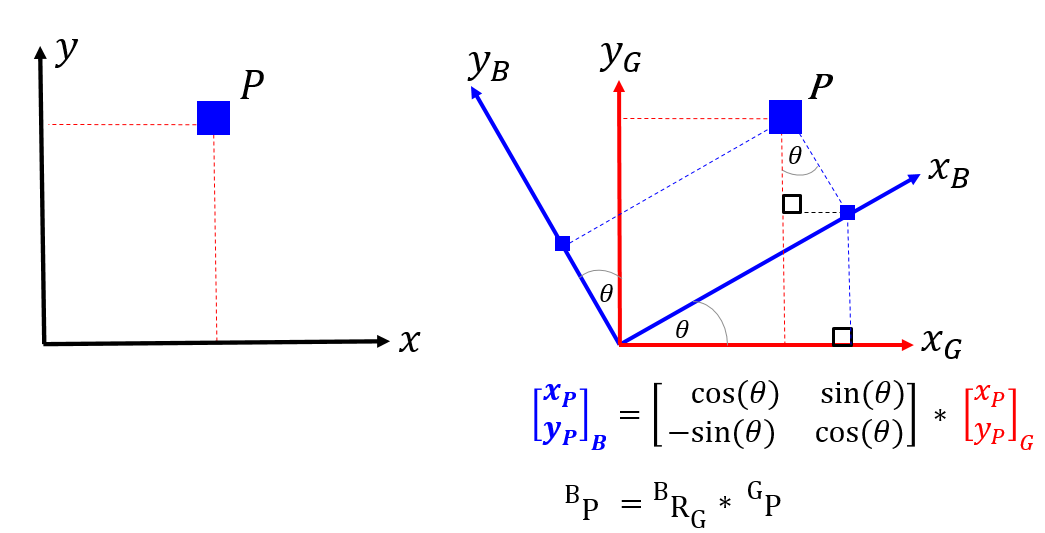 

A **PASSIVE** rotation matrix, converts the co-ordinates of a point expressed in a fixed **G-frame**, into the co-ordinates of the same point expressed in the new **B-frame**. 

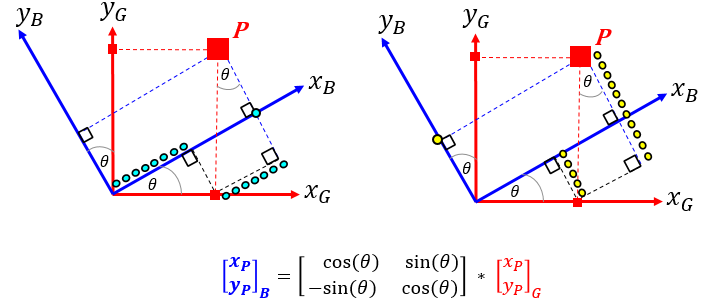

## An example of 3 successive PASSIVE rotations

Say we have a fixed G-frame. We start by having our B-frame co-incident with G, and then we start to rotate the B-frame. Specifically, we're going to apply 3 LOCAL axes rotations which will result in a newly orientated B-frame.  Assume that we apply these 3 successive rotations in the following order:

- R1Z occurs 1st about the LOCAL **Z** body axis $(\phi)$, aka **YAW**

- R2Y occurs 2nd about the LOCAL **Y** body axis $(\theta)$, aka **PITCH**

- R3X occurs 3rd about the LOCAL **X** body axis $(\psi)$, aka **ROLL**

We can express a vector defined in the G axis to it's corresponding description in the B axis, using a sequence of **PASSIVE** rotation matrices, ie:


$$\bf ^Bv = R3X(\psi_x) \enspace \times \enspace 
R2Y(\theta_y) \enspace \times \enspace R1Z(\phi_z) \enspace \times \enspace {^Gv}$$


    OR, in a more compact form as:


$$\bf ^Bv = {^BR_G} \enspace \times \enspace {^Gv}$$


## Create a passive rotation object

syms phi theta psi
OBJ_P = bh_rot_passive_G2B_CLS({'D1Z', 'D2Y', 'D3X'}, [phi, theta, psi], 'SYM')

OBJ_P =   bh_rot_passive_G2B_CLS with properties:

        ang_units: SYM
    num_rotations: 3
          dir_1st: D1Z
          dir_2nd: D2Y
          dir_3rd: D3X
          ang_1st: [1×1 sym]
          ang_2nd: [1×1 sym]
          ang_3rd: [1×1 sym]


## Here are the PASSIVE rotation matrices:

Here's  $\bf  R1Z(\phi_z) $:

R1Z = OBJ_P.get_R1

$$R1Z = \left(\begin{array}{ccc} \cos\left(\phi \right) & \sin\left(\phi \right) & 0\\ -\sin\left(\phi \right) & \cos\left(\phi \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

Here's $\bf 
R2Y(\theta_y) $:

R2Y = OBJ_P.get_R2

$$R2Y = \left(\begin{array}{ccc} \cos\left(\theta \right) & 0 & -\sin\left(\theta \right)\\ 0 & 1 & 0\\ \sin\left(\theta \right) & 0 & \cos\left(\theta \right) \end{array}\right)$$

Here's $\bf R3X(\psi_x) $

R3X = OBJ_P.get_R3

$$R3X = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\psi \right) & \sin\left(\psi \right)\\ 0 & -\sin\left(\psi \right) & \cos\left(\psi \right) \end{array}\right)$$

## Calculate the Direction Cosine Matrix  ${^{B}}R_G $

Recall we earlier said:          $^{B}v  = {^{B}}R_G *  {^{G}}v$

bRg = R3X * R2Y * R1Z

$$bRg = \left(\begin{array}{ccc} \cos\left(\phi \right)\,\cos\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\phi \right) & -\sin\left(\theta \right)\\ \cos\left(\phi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\phi \right) & \cos\left(\phi \right)\,\cos\left(\psi \right)+\sin\left(\phi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\psi \right)\\ \sin\left(\phi \right)\,\sin\left(\psi \right)+\cos\left(\phi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\phi \right)\,\sin\left(\theta \right)-\cos\left(\phi \right)\,\sin\left(\psi \right) & \cos\left(\psi \right)\,\cos\left(\theta \right) \end{array}\right)$$

## Explore the relationship between BODY rates and EULER rates

As we apply these local frame rotations of ($\phi, \theta, \psi$), we can represent the **angular rates** ($\dot{\phi}, \dot{\theta}, \dot{\matrix{\psi}}$) of the rotating frames into the LOCAL frame co-ordinates. These local frame co-ordinates can then be converted into co-ordinates expressed in the final B frame.  For example, during each of the local axes rotations we can think of there being a START frame and an END frame:

      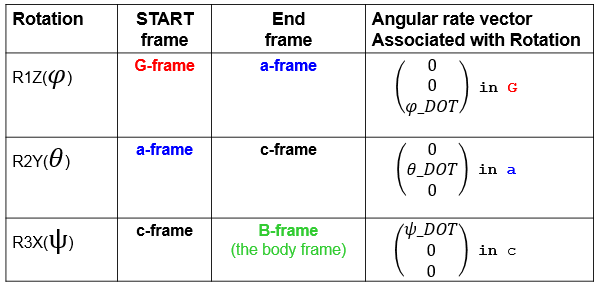

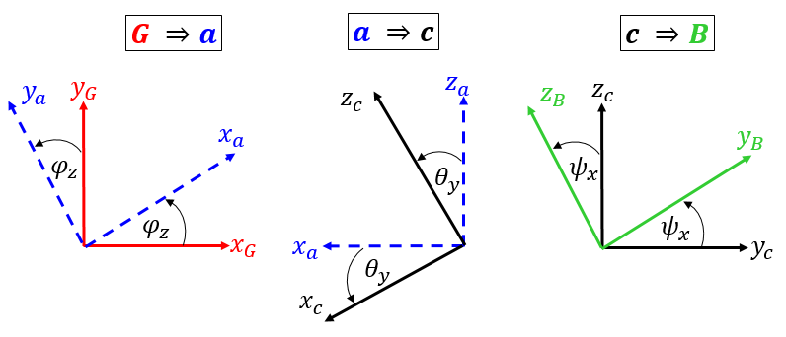

We can express each of the local frame angular velocities into their corresponding components in the final B frame - and we'll use PASSIVE rotation matrices to do this:

syms phi_dot  theta_dot  psi_dot

aRg = R1Z;
cRa = R2Y;
bRc = R3X;

Here's the portion of the BODY frame rate associated with our $\dot{ \matrix{\phi}}$ rate:

wb_part_1 = bRc * cRa * aRg * [0;0;phi_dot]   % convert local G into B

$$wb\_part\_1 = \left(\begin{array}{c} -\phi_{\mathrm{dot}}\,\sin\left(\theta \right)\\ \phi_{\mathrm{dot}}\,\cos\left(\theta \right)\,\sin\left(\psi \right)\\ \phi_{\mathrm{dot}}\,\cos\left(\psi \right)\,\cos\left(\theta \right) \end{array}\right)$$

Here's the portion of the BODY frame rate associated with our $\dot{ \matrix{\theta}}$ rate:

wb_part_2 = bRc * cRa *       [0;theta_dot;0] % convert local a into B

$$wb\_part\_2 = \left(\begin{array}{c} 0\\ \theta_{\mathrm{dot}}\,\cos\left(\psi \right)\\ -\theta_{\mathrm{dot}}\,\sin\left(\psi \right) \end{array}\right)$$

Here's the portion of the BODY frame rate associated with our $\dot{ \matrix{\psi}}$ rate:

wb_part_3 = bRc *             [psi_dot;0;0]   % convert local c into B

$$wb\_part\_3 = \left(\begin{array}{c} \psi_{\mathrm{dot}}\\ 0\\ 0 \end{array}\right)$$

## The total angular velocity expressed in the BODY B frame is therefore

We can now construct the total angular velocity vector expressed in components of the final B frame.


$$_G^{B}\omega_b \equiv \omega_b = f( \dot{ \matrix{\phi}}, \dot{ \matrix{\theta}}, \dot{ \matrix{\psi}}, \phi, \theta, \psi) $$
 

wb = wb_part_1 + wb_part_2 + wb_part_3

$$wb = \left(\begin{array}{c} \psi_{\mathrm{dot}}-\phi_{\mathrm{dot}}\,\sin\left(\theta \right)\\ \theta_{\mathrm{dot}}\,\cos\left(\psi \right)+\phi_{\mathrm{dot}}\,\cos\left(\theta \right)\,\sin\left(\psi \right)\\ \phi_{\mathrm{dot}}\,\cos\left(\psi \right)\,\cos\left(\theta \right)-\theta_{\mathrm{dot}}\,\sin\left(\psi \right) \end{array}\right)$$

## We can write the angular velocity vector $\omega_b$ as a MATRIX equation

Let's say that:  $ \omega_b = \pmatrix{p \cr q \cr r}
$, we can write a matrix equation of the form **A.x = b** that describes the relationship between the body rates $\omega_b$ and the Euler rates:  $A \times   \pmatrix{ \phi_{dot} \cr \theta_{dot} \cr \psi_{dot} }  =  \pmatrix{p \cr q \cr r}  $  

syms p q r

x = [phi_dot, theta_dot, psi_dot].';
    
[A,b] = equationsToMatrix(  wb(1)==p, ...
                            wb(2)==q, ...
                            wb(3)==r, ...
                            x); 

Just to clarify this, let me put each of the 3 elements side by side as  [**A, x, b] ,** where:


$$\matrix{
A & \times & x & = & b \cr
\downarrow & & \downarrow & & \downarrow \cr
A & \times & \pmatrix{\dot{\matrix{\phi}} \cr \dot{\matrix{\theta}}  \cr \dot{\matrix{\psi}}  } & = & \pmatrix{ ^B\omega_x \cr ^B\omega_y \cr ^B\omega_z} 

}$$


[A, x, b]                       

$$ans = \left(\begin{array}{ccccc} -\sin\left(\theta \right) & 0 & 1 & \phi_{\mathrm{dot}} & p\\ \cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\psi \right) & 0 & \theta_{\mathrm{dot}} & q\\ \cos\left(\psi \right)\,\cos\left(\theta \right) & -\sin\left(\psi \right) & 0 & \psi_{\mathrm{dot}} & r \end{array}\right)$$

## Introducing the 3D pendulum:

Our 3D pendulum looks like this:

##   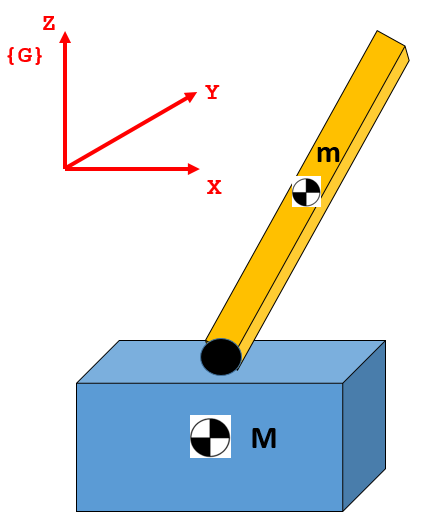     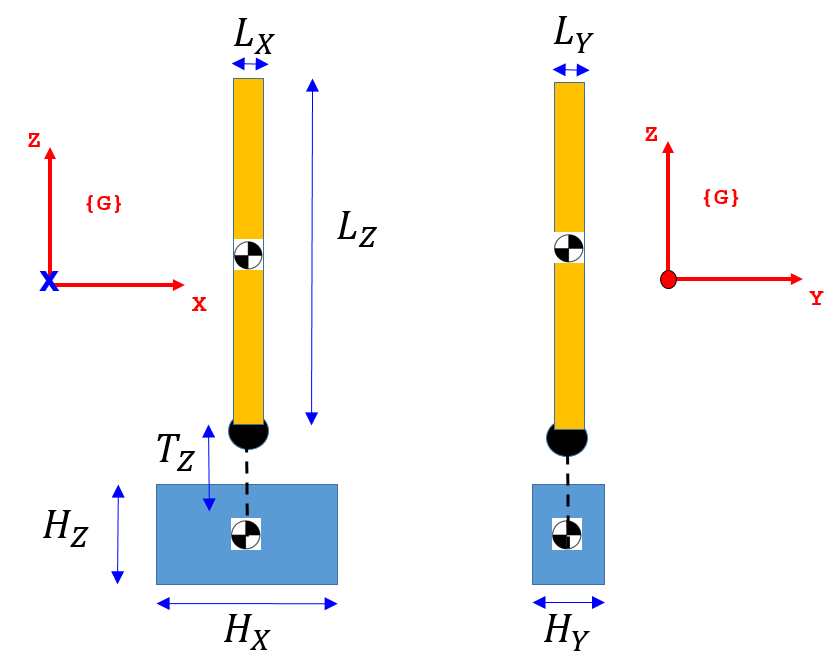

- The pendulum is attached to the base cart via a spherical joint.  

- The sperical joint permits the pendulum to yaw, pitch and roll.  

- The base cart may translate in the inertial X,Y, and Z directions.

- We will be applying forces to the Base cart only

- We will represent the base cart as a point mass.

## Defining the some model parameters:

syms  m_pend  M_cart g
syms  Tv_Z  Lx  Ly  Lz

## Defining the pendulum INERTIA:

So let's define the INERTIA matrix for the pendulum about its body fixed **center of mass** frame:

   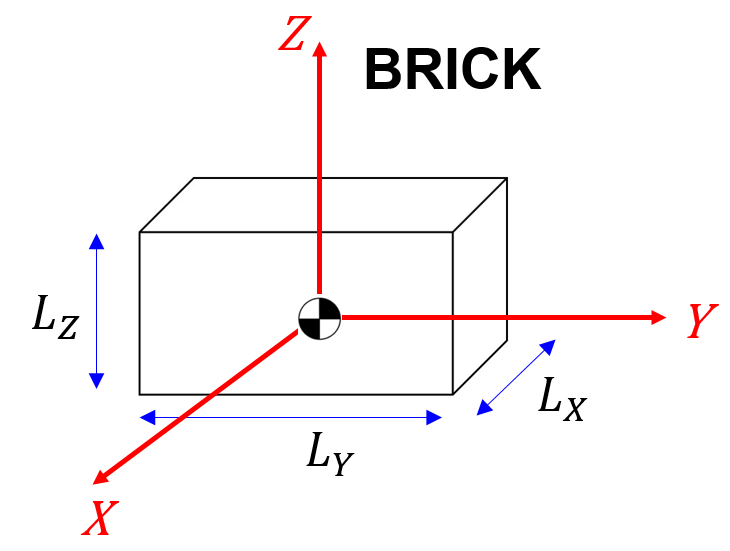

I_pend = ...
      m_pend *[    (Ly^2 + Lz^2)/12,    0,                    0; ...
                    0,                 (Lx^2 + Lz^2)/12,      0; ...
                    0,                  0,                   (Lx^2 + Ly^2)/12;] ; 

Euler angles for the pendulum:

syms        Phi(t)      Theta(t)       Psi(t)    
syms    THE_Phi     THE_Theta      THE_Psi

INERTIAL {G}-frame co-ordinates for the BASE cart and the FORCES on the cart:

syms            X(t)        Y(t)         Z(t)
syms        THE_X       THE_Y        THE_Z
syms         Fg_X        Fg_Y         Fg_Z 

Define the Direction Cosine matrix using our NEW symbols:

bRg = subs(bRg, [phi, theta, psi],[Phi(t)      Theta(t)       Psi(t)])

$$bRg = \left(\begin{array}{ccc} \cos\left(\Phi \left(t\right)\right)\,\cos\left(\Theta \left(t\right)\right) & \cos\left(\Theta \left(t\right)\right)\,\sin\left(\Phi \left(t\right)\right) & -\sin\left(\Theta \left(t\right)\right)\\ \cos\left(\Phi \left(t\right)\right)\,\sin\left(\Psi \left(t\right)\right)\,\sin\left(\Theta \left(t\right)\right)-\cos\left(\Psi \left(t\right)\right)\,\sin\left(\Phi \left(t\right)\right) & \cos\left(\Phi \left(t\right)\right)\,\cos\left(\Psi \left(t\right)\right)+\sin\left(\Phi \left(t\right)\right)\,\sin\left(\Psi \left(t\right)\right)\,\sin\left(\Theta \left(t\right)\right) & \cos\left(\Theta \left(t\right)\right)\,\sin\left(\Psi \left(t\right)\right)\\ \sin\left(\Phi \left(t\right)\right)\,\sin\left(\Psi \left(t\right)\right)+\cos\left(\Phi \left(t\right)\right)\,\cos\left(\Psi \left(t\right)\right)\,\sin\left(\Theta \left(t\right)\right) & \cos\left(\Psi \left(t\right)\right)\,\sin\left(\Phi \left(t\right)\right)\,\sin\left(\Theta \left(t\right)\right)-\cos\left(\Phi \left(t\right)\right)\,\sin\left(\Psi \left(t\right)\right) & \cos\left(\Psi \left(t\right)\right)\,\cos\left(\Theta \left(t\right)\right) \end{array}\right)$$

Define the Pendulum's angular velocity using our NEW symbols:

                % OLD_list          NEW_list
A       = subs(A, [phi, theta, psi], [Phi(t), Theta(t), Psi(t)])

$$A = \left(\begin{array}{ccc} -\sin\left(\Theta \left(t\right)\right) & 0 & 1\\ \cos\left(\Theta \left(t\right)\right)\,\sin\left(\Psi \left(t\right)\right) & \cos\left(\Psi \left(t\right)\right) & 0\\ \cos\left(\Psi \left(t\right)\right)\,\cos\left(\Theta \left(t\right)\right) & -\sin\left(\Psi \left(t\right)\right) & 0 \end{array}\right)$$


e_dot   = [ diff(Phi(t),   t);
            diff(Theta(t), t); 
            diff(Psi(t),   t) ]

$$e\_dot = \left(\begin{array}{c} \frac{\partial }{\partial t}\Phi \left(t\right)\\ \frac{\partial }{\partial t}\Theta \left(t\right)\\ \frac{\partial }{\partial t}\Psi \left(t\right) \end{array}\right)$$


w_pend  = A * e_dot;      

## Define the Cart's Kinetic and Potential energy:

v_col = [diff(X(t),t); diff(Y(t),t); diff(Z(t),t);];

KE_cart = (1/2)* v_col.'  * M_cart * v_col;
PE_cart = M_cart*g*Z(t);

## Define the Pendulum's Kinetic and Potential energy:

 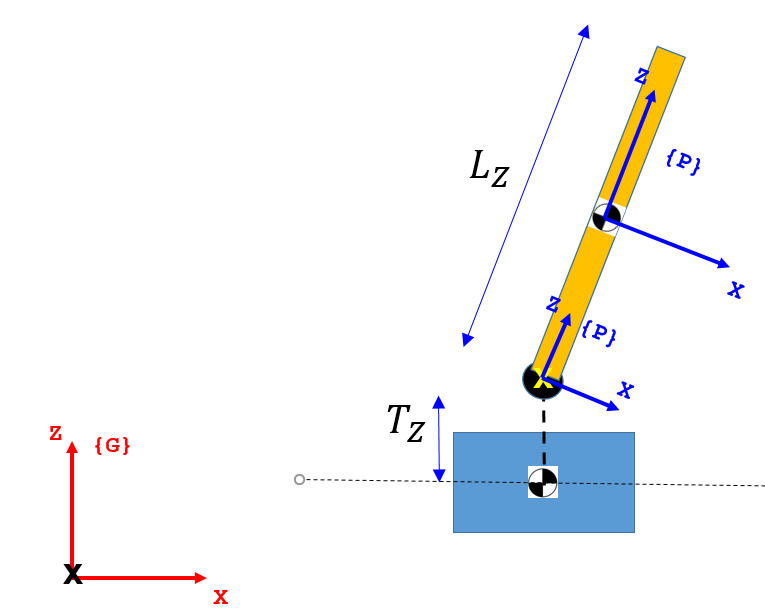

The position of the pendulum's center of mass according to a BODY FIXED frame attached to the sperical joint is:

rp = [0;0;Lz/2];

Therefore, the position of the pendulum's centre of mass according to the {G}-frame is:

gRb     = bRg.';
rg_tmp  = gRb * rp

$$rg\_tmp = \left(\begin{array}{c} \frac{\mathrm{Lz}\,\left(\sin\left(\Phi \left(t\right)\right)\,\sin\left(\Psi \left(t\right)\right)+\cos\left(\Phi \left(t\right)\right)\,\cos\left(\Psi \left(t\right)\right)\,\sin\left(\Theta \left(t\right)\right)\right)}{2}\\ -\frac{\mathrm{Lz}\,\left(\cos\left(\Phi \left(t\right)\right)\,\sin\left(\Psi \left(t\right)\right)-\cos\left(\Psi \left(t\right)\right)\,\sin\left(\Phi \left(t\right)\right)\,\sin\left(\Theta \left(t\right)\right)\right)}{2}\\ \frac{\mathrm{Lz}\,\cos\left(\Psi \left(t\right)\right)\,\cos\left(\Theta \left(t\right)\right)}{2} \end{array}\right)$$


rg = [X(t); Y(t); Z(t)]  +  [0;0;Tv_Z]   +   rg_tmp;

So the translational velocity of the Pendulum's centre of mass is:

vcg_pend_col = diff(rg, t);

So the **Pendulum's Potential Energy** is:

PE_pend = m_pend*g*rg(3);

So the **Pendulum's Kinetic Energy** is:

KE_pend = (1/2)* vcg_pend_col.' * m_pend * vcg_pend_col   + ...
          (1/2)* w_pend.'       * I_pend * w_pend

**The SYSTEM Kinetic and Potential energy is therefore:**

KE = KE_cart  +  KE_pend;
PE = PE_cart  +  PE_pend;

# Prepare for the Computation of the Generalised Forces:

Shortly we'll calculate the generalised force *Q* :


$$Q_k = 
\sum_{i=1}^{Nf_{nc}}
\pmatrix{
\vec{F_i} \thinspace . \thinspace \frac{\partial \vec{v \thinspace _i}}{\partial \dot{q \thinspace}_k}
}  \enspace + \enspace
\sum_{j=1}^{N\tau_{nc}}
\pmatrix{
\vec {\tau_j} \thinspace . \thinspace \frac{\partial \vec{\omega \thinspace _j}}{\partial \dot{q \thinspace}_k}
}
$$


First we'll define all of the active forces acting on the system (remember that GRAVITY is catered for by the system's potential energy):

v_col = [ diff(X(t),t);   diff(Y(t),t);    diff(Z(t),t);]

$$v\_col = \left(\begin{array}{c} \frac{\partial }{\partial t}X\left(t\right)\\ \frac{\partial }{\partial t}Y\left(t\right)\\ \frac{\partial }{\partial t}Z\left(t\right) \end{array}\right)$$


F_mat = [   Fg_X,       0,        0;
               0,    Fg_Y,        0;
               0,       0,     Fg_Z;    ];
          
v_mat = [  v_col,   v_col,     v_col    ];

# Apply Lagrange's equation - PART 1 of 3 

To derive the equations of motion for our machine, "all" we need to do is a series of derivative calculations according to Lagrange's equation:

 
$$\frac{d}{dt}\frac{\partial L}{\partial \dot{q}_k} - \frac{\partial L}{\partial q_k} = Q_k $$
 

Where:

- *L = KE - PE, *is our system lagrangian

- $q_k = \{ \Phi, \Theta, \psi, {^GX}, {^GY}, {^GZ} \}$ are the generalised co-ordinates 

- $Q_k$ are the generalised forces (Forces and Torques) for our system

Recall our list of generalised co-ordinates:

actual_list_SYM_pos = [    Phi(t),      Theta(t),       Psi(t),        X(t),       Y(t),      Z(t)];
holder_list_SYM_pos = [THE_Phi,     THE_Theta,      THE_Psi,       THE_X       THE_Y      THE_Z   ];

Now let's create a Lagrangian object using the class <`bh_lagr4manips_CLS`>

lag_OBJ = bh_lagr4manips_CLS( KE, PE, actual_list_SYM_pos, holder_list_SYM_pos);

And let's compute the system's equations of motion:

lag_OBJ = lag_OBJ.calc_eom()

lag_OBJ =   bh_lagr4manips_CLS with properties:

                   T_KE: [1×1 sym]
                   V_PE: [1×1 sym]
                      L: [1×1 sym]
                Qk_list: [6×1 sym]
                    EOM: [1×6 bh_eom_CLS]
                  N_dof: 6
    actual_list_SYM_pos: [6×1 sym]
    actual_list_SYM_vel: [6×1 sym]
    actual_list_SYM_acc: [6×1 sym]
    holder_list_SYM_pos: [6×1 sym]
    holder_list_SYM_vel: [6×1 sym]
    holder_list_SYM_acc: [6×1 sym]


So what do the equations of motion actually look like ? - they are long equations involving many terms

lag_OBJ.show_eom()


#######################################################
### q = Phi(t)
### 
### LHS of EOM is: 
### 
        (Lz*m_pend*(sin(Phi(t))*sin(Psi(t)) + cos(Phi(t))*cos(Psi(t))*sin(Theta(t)))*((Lz*(cos(Phi(t))*sin(Psi(t))*diff(Phi(t), t)^2 + cos(Phi(t))*sin(Psi(t))*diff(Psi(t), t)^2 - cos(Phi(t))*cos(Psi(t))*diff(Psi(t), t, t) + sin(Phi(t))*sin(Psi(t))*diff(Phi(t), t, t) - sin(Phi(t))*sin(Psi(t))*sin(Theta(t))*diff(Psi(t), t, t) - cos(Psi(t))*sin(Phi(t))*sin(Theta(t))*diff(Phi(t), t)^2 - cos(Psi(t))*sin(Phi(t))*sin(Theta(t))*diff(Psi(t), t)^2 + 2*cos(Psi(t))*sin(Phi(t))*diff(Phi(t), t)*diff(Psi(t), t) - cos(Psi(t))*sin(Phi(t))*sin(Theta(t))*diff(Theta(t), t)^2 + cos(Phi(t))*cos(Psi(t))*sin(Theta(t))*diff(Phi(t), t, t) + cos(Psi(t))*cos(Theta(t))*sin(Phi(t))*diff(Theta(t), t, t) + 2*cos(Phi(t))*cos(Psi(t))*cos(Theta(t))*diff(Phi(t), t)*diff(Theta(t), t) - 2*cos(Phi(t))*sin(Psi(t))*sin(Theta(t))*diff(Phi(t), t)*diff(Psi(t), t) - 2*cos(Theta(t))*sin(Phi(t))*sin(Psi(t))*diff(Psi(t), t)*diff(The

If you want to look at an individual equation of motion (eg: the LHS of the $4\mathrm{th}$ equation), then you could do this:

lag_OBJ.get_eom(4, 'actual', 'LHS')

In a moment we'll show how to "collect" the terms in these EOMs and present them in a format that looks like this:

- 
$$M(q,\dot{q}).\ddot{q} \enspace + \enspace
C(q,\dot{q}).\dot{q} \enspace + \enspace
K(q).q \enspace + \enspace
 g(q) = Q(\tau, \dot{q})$$


Next we'll create a generalised force object using the class <`bh_genF4manips_CLS`>

genF_OBJ = bh_genF4manips_CLS( F_mat, ...
                               v_mat, ...
                               actual_list_SYM_pos, ...
                               holder_list_SYM_pos);

And now calculate our system's generalised forces:                 

genF_OBJ = genF_OBJ.calc_genF();

What do the $Q_k's$ look like?

the_Qk_vec = genF_OBJ.get_Qk('all', 'holder')

$$the\_Qk\_vec = \left(\begin{array}{c} 0\\ 0\\ 0\\ {\mathrm{Fg}}_{X}\\ {\mathrm{Fg}}_{Y}\\ {\mathrm{Fg}}_{Z} \end{array}\right)$$

**Absorb the Generalised Forces:** We can now insert these Generalised forces into the "Lagrangian" object that we created earlier, and then recalculate the equations of motion:  

lag_OBJ = lag_OBJ.calc_eom(genF_OBJ);

 Now echo our equations:

lag_OBJ.show_eom( )


#######################################################
### q = Phi(t)
### 
### LHS of EOM is: 
### 
        (Lz*m_pend*(sin(Phi(t))*sin(Psi(t)) + cos(Phi(t))*cos(Psi(t))*sin(Theta(t)))*((Lz*(cos(Phi(t))*sin(Psi(t))*diff(Phi(t), t)^2 + cos(Phi(t))*sin(Psi(t))*diff(Psi(t), t)^2 - cos(Phi(t))*cos(Psi(t))*diff(Psi(t), t, t) + sin(Phi(t))*sin(Psi(t))*diff(Phi(t), t, t) - sin(Phi(t))*sin(Psi(t))*sin(Theta(t))*diff(Psi(t), t, t) - cos(Psi(t))*sin(Phi(t))*sin(Theta(t))*diff(Phi(t), t)^2 - cos(Psi(t))*sin(Phi(t))*sin(Theta(t))*diff(Psi(t), t)^2 + 2*cos(Psi(t))*sin(Phi(t))*diff(Phi(t), t)*diff(Psi(t), t) - cos(Psi(t))*sin(Phi(t))*sin(Theta(t))*diff(Theta(t), t)^2 + cos(Phi(t))*cos(Psi(t))*sin(Theta(t))*diff(Phi(t), t, t) + cos(Psi(t))*cos(Theta(t))*sin(Phi(t))*diff(Theta(t), t, t) + 2*cos(Phi(t))*cos(Psi(t))*cos(Theta(t))*diff(Phi(t), t)*diff(Theta(t), t) - 2*cos(Phi(t))*sin(Psi(t))*sin(Theta(t))*diff(Phi(t), t)*diff(Psi(t), t) - 2*cos(Theta(t))*sin(Phi(t))*sin(Psi(t))*diff(Psi(t), t)*diff(The

# Isolate the term of interest  M,C,K,G

We can express our system equations of motion in the following form:


$$M(q,\dot{q}).\ddot{q} \enspace + \enspace
C(q,\dot{q}).\dot{q} \enspace + \enspace
K(q).q \enspace + \enspace
 g(q) = Q(\tau, \dot{q})$$


 lag_OBJ = lag_OBJ.create_MCKGQ();

Retrieve the MCKGQ struct:

res_T = lag_OBJ.get_MCKGQ()

res_T =   bh_MCKGQ_CLS with properties:

           M: [6×6 sym]
           C: [6×6 sym]
           K: [6×6 sym]
           G: [6×1 sym]
           Q: [6×1 sym]
     ACC_col: [6×1 sym]
     VEL_col: [6×1 sym]
     POS_col: [6×1 sym]
    acc_eoms: [1×1 sym]


fh_BOUNDARY = @(txt)fprintf('\n %s \n Here is the %s matrix: \n',repmat('#',1,75),txt);

Here's **M**:

fh_BOUNDARY('M');  res_T.M


 ########################################################################### 
 Here is the M matrix: 


Here's **C**:

fh_BOUNDARY('C');  res_T.C


 ########################################################################### 
 Here is the C matrix: 


Here's **K**:

fh_BOUNDARY('K');  res_T.K


 ########################################################################### 
 Here is the K matrix: 


$$ans = \left(\begin{array}{cccccc} 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

Here's **G**:

fh_BOUNDARY('G');  res_T.G


 ########################################################################### 
 Here is the G matrix: 


$$ans = \left(\begin{array}{c} 0\\ -\frac{\mathrm{Lz}\,g\,m_{\mathrm{pend}}\,\cos\left({\mathrm{THE}}_{\Psi }\right)\,\sin\left({\mathrm{THE}}_{\Theta }\right)}{2}\\ -\frac{\mathrm{Lz}\,g\,m_{\mathrm{pend}}\,\cos\left({\mathrm{THE}}_{\Theta }\right)\,\sin\left({\mathrm{THE}}_{\Psi }\right)}{2}\\ 0\\ 0\\ g\,\left(M_{\mathrm{cart}}+m_{\mathrm{pend}}\right) \end{array}\right)$$

Here's **Q**:

fh_BOUNDARY('Q');  res_T.Q


 ########################################################################### 
 Here is the Q matrix: 


$$ans = \left(\begin{array}{c} 0\\ 0\\ 0\\ {\mathrm{Fg}}_{X}\\ {\mathrm{Fg}}_{Y}\\ {\mathrm{Fg}}_{Z} \end{array}\right)$$

# Convert symbolic EoM expressions into a block diagram model

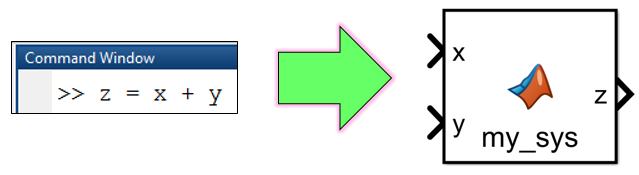

To use/solve these derived equations of motion we'll create a MATLAB Function block that can be used inside Simulink:

lag_OBJ.create_MLF_blocks()

Evaluating callback 'PostLoadFcn' for simulink
Callback: setsysloc_simulink(bdroot)
Evaluating callback 'LoadFcn' for simulink/Sources/Waveform Generator
Callback: set_param(gcb,'LoadFlag','1');


Evaluating callback 'LoadFcn' for simulink/Sources/Signal Builder
Callback: sigbuilder_block('load');
Evaluating callback 'LoadFcn' for simulink/Sinks/XY Graph
Callback: sfunxy([],[],[],'LoadBlock')
Evaluating callback 'LoadFcn' for simulink/Model-Wide Utilities/Model Info
Callback: slcm LoadBlock;
Evaluating callback 'LoadFcn' for simulink/Math Operations/Slider Gain
Callback: sliderGain_cb(gcbh, 'load');
